## **Relative Power**

Pskid = Proll if $\frac{\mu_s }{\mu_r }\;\sin \alpha =1$

$\frac{\mu_s }{\mu_r }$ = 5, where  $\mu_s$ = 1 and $\mu_r$ = 0.2

r = turning radius

l = length (m) between the front and rear axles

v = velocity of the rover in m/s

N = Normal force into soil


$$P=\left(2r+\sqrt{{\left(r-\frac{c}{2}\right)}^2 +l^2 }+\sqrt{{\left(r+\frac{c}{2}\right)}^2 +l^2 }\right)*\frac{v}{r}\mu_r N$$


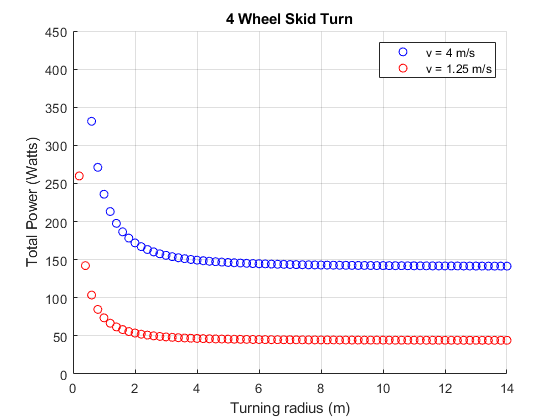

clc
clear all
ur = 0.2;
r = 0:0.2:14;
l = 2;
c = 1.6;
v1 = 4;
v2 = 1.25;

N = 44;
for i = 1:length(r)
    P1 =((2*r(i) + sqrt((r(i)-c/2).^2+(l^2)) + sqrt((r(i)+c/2).^2+(l^2)))*((v1/r(i))*ur*N)); 
    P2 = ((2*r(i) + sqrt((r(i)-c/2).^2+(l^2)) + sqrt((r(i)+c/2).^2+(l^2)))*((v2/r(i))*ur*N));
    figure(1)
    hold on
    scatter(r(i),P1,'blue')
    scatter(r(i),P2,'red')
end

hold off
xlabel('Turning radius (m)')
ylabel("Total Power (Watts)")
ylim([[0 450]])
grid on
title('4 Wheel Skid Turn')
legend('v = 4 m/s','v = 1.25 m/s')